# Test Controllers

clear
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));

#### Load DGU Network parameters from file and initialize the class for the DGU Network

- Constant variables for the rest of the analysis:

%set(groot,'defaultfigureposition',[400 250 780 680])
clear
length_sim = 50;
simStart = 1;
utils = utilityFunctions; % utility function class
sim = SimFunctionsPnP; % simulation function class
filename = 'config_DGU_1.txt'; % Initial DGU Network
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

    {'subsystems'}    {'Vin'}    {'R     '}    {'L     '}    {'C    '}    {'Vmax'}    {'Vmin'}    {'Imax'}    {'Imin'}

    6.0000  100.0000    0.0030    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0017    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   51.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   51.0000   49.0000   10.0000         0



activeDGU = 1:nb_subsystems; % all DGU are active

#### Define the resistor values connecting the DGUs i.e. interconnection strengths.

Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8;

Make the interconnection between DGU 3 and DGU 6 variable:

Rij_mat(3,6) = 2;
Rij_mat = Rij_mat + tril(Rij_mat',1); % symmetric matrix for undirected graph
%% Instantiate DGU NETWORK
dguNet = DGU_network(nb_subsystems);
dguNet = dguNet.setConnectionsGraph(Rij_mat);
dguNet = dguNet.setActiveDGU(activeDGU);

- Plot the Graph describing the Network

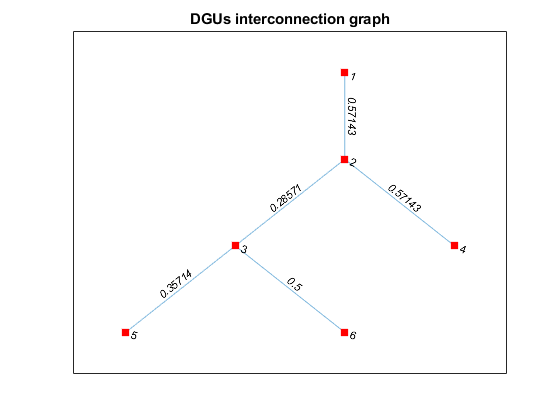

plot(dguNet.NetGraph, 'EdgeLabel', dguNet.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title("DGUs interconnection graph")

- Set references $V_r$ [V] to converge to and load current $I_l$ [A]

Vr = linspace(49.95, 50.05, nb_subsystems); % references
Il = linspace(2.5, 7.5, nb_subsystems);
% set Electrical parameters
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end
dguNet = dguNet.initDynamics();

#### Test the Passivity controller, $\Delta$ Formulation of constraints to converge to references

delta_config = true; % Delta-Formulation of DGU Network
dguNet = dguNet.compute_Ref_Constraints(delta_config); % constraints in delta formulation
control_type = "PASSIVITY";
config = "DISTRIBUTED";
dguNet = sim.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312



ans = "K2"

   -0.0107   -0.1036



ans = "P2"

    2.9563    0.5613
    0.5613    4.2433



ans = "K3"

   -0.4541   -0.1514



ans = "P3"

   13.9185    1.1789
    1.1789    0.5920



ans = "K4"

   -0.0230   -0.0931



ans = "P4"

    5.2771    0.7380
    0.7380    3.2252



ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6917
    4.6917    1.6810



ans = "K6"

   -0.4567   -0.1333



ans = "P6"

   36.6077    3.3840
    3.3840    1.5383

Smallest among all subsystem minimum eigenvalue of dissipation rate 9.97e-02 


passivity = true; % set passivity boolean to true
[x0, ~, ~, ~] = utils.tuningParam(dguNet, delta_config, passivity) % initial parameters definition

Qi and Ri found to guarantee asympt. stability of the global system 


x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


[X,U] = sim.sim_DGU_distributed(x0, length_sim, dguNet, dguNet.Ki);
error_pass = utils.tracking_error(X,U,config,dguNet,activeDGU)

error_pass = 4.8348

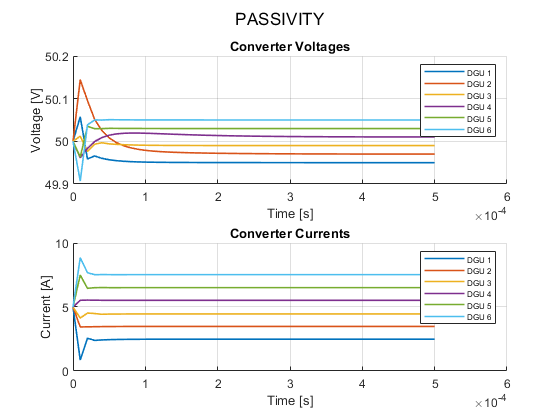

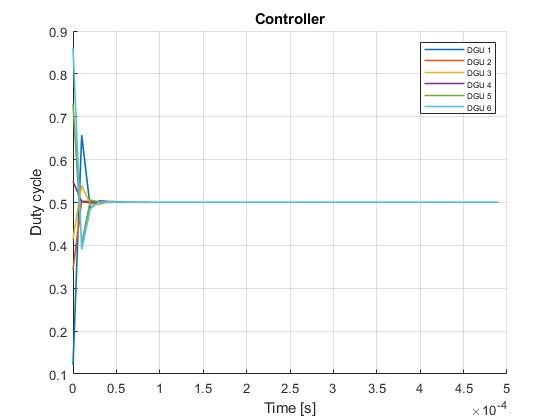

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart,activeDGU);

#### Evaluate Passivity controller by comparing it to LQR

config = "GENERAL";
control_type = 'LQR';
Ad = dguNet.global_sysd.A; Bd = dguNet.global_sysd.B; 
Q = eye(size(Ad,1)); R = eye(size(Bd,2));
disp("LQR controller Gain");

LQR controller Gain


[Klqr, Pinf, ~] = dlqr(Ad, Bd, Q,R)

Klqr =     0.0459    0.0946    0.0144    0.0015    0.0027    0.0002    0.0072    0.0006    0.0005    0.0000    0.0007    0.0001
    0.0249    0.0017    0.0255    0.1040    0.0086    0.0008    0.0229    0.0018    0.0027    0.0002    0.0033    0.0003
    0.0040    0.0003    0.0074    0.0007    0.0296    0.1021    0.0036    0.0003    0.0178    0.0013    0.0215    0.0017
    0.0089    0.0006    0.0167    0.0017    0.0030    0.0003    0.0458    0.0973    0.0006    0.0000    0.0008    0.0001
    0.0006    0.0000    0.0017    0.0002    0.0131    0.0012    0.0005    0.0000    0.0525    0.0954    0.0049    0.0004
    0.0009    0.0001    0.0024    0.0002    0.0181    0.0016    0.0008    0.0001    0.0055    0.0004    0.0481    0.0975


Pinf =     5.7849    0.3284    1.3492    0.1357    0.2567    0.0223    0.6823    0.0535    0.0563    0.0038    0.0726    0.0055
    0.3284    1.0310    0.0889    0.0089    0.0166    0.0014    0.0442    0.0035    0.0035    0.0002    0.0046    0.0003
    1.3492    0.0889    2.7659    0.1891    0.4783    0.0426    1.2606    0.1008    0.1527    0.0107    0.1884    0.0147
    0.1357    0.0089    0.1891    1.0307    0.0479    0.0042    0.1263    0.0101    0.0148    0.0010    0.0183    0.0014
    0.2567    0.0166    0.4783    0.0479    3.2852    0.2160    0.2332    0.0182    1.1156    0.0799    1.3559    0.1084
    0.0223    0.0014    0.0426    0.0042    0.2160    1.0304    0.0202    0.0016    0.0992    0.0071    0.1207    0.0096
    0.6823    0.0442    1.2606    0.1263    0.2332    0.0202    4.8870    0.3242    0.0513    0.0035    0.0658    0.0050
    0.0535    0.0035    0.1008    0.0101    0.0182    0.0016    0.3242    1.0359    0.0039    0.0003    0.0050    0.0004
    0.0563    0.0035    0

[Xlqr,Ulqr] = sim.sim_global_DGU(x0, length_sim, dguNet, -Klqr);
error_lqr = utils.tracking_error(Xlqr,Ulqr,config,dguNet,activeDGU)

error_lqr = 4.3304

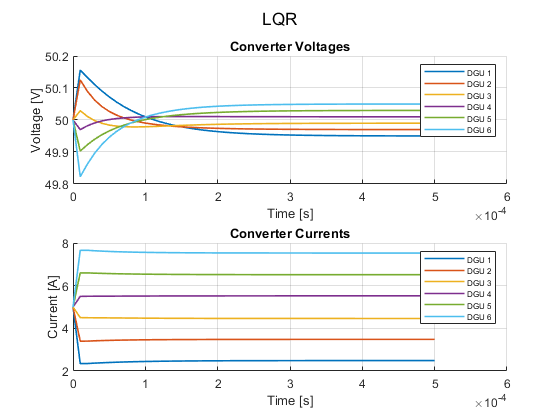

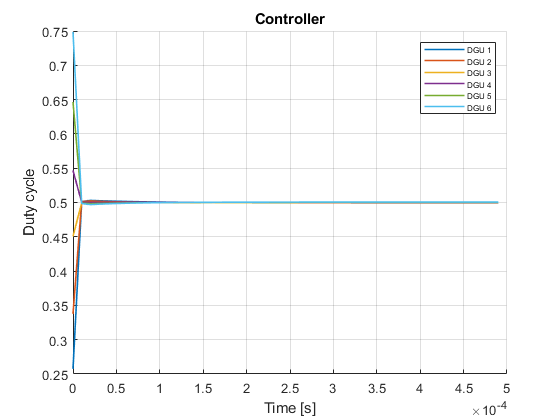

dguNet.plot_DGU_system(Xlqr,Ulqr, config, control_type, dguNet, simStart, activeDGU)

- Compute the suboptimality index $\frac{e_{pbc} - e_{lqr}}{e_{lqr}}$  where the tracking error is defined as:

$e=\sqrt{\sum_{k=0}^{T} \sum_{i=1}^{6}\left(\Delta V_{i}^{k^{2}}+\Delta I_{i}^{k^{2}}+\Delta u_{i}^{k^{2}}\right)}$ is computed where $\Delta V_{i}^{k}=V_{i}^{k}-V_{r_{i}}, \Delta I_{i}^{k}=I_{i}^{k}-I_{r_{i}}$, $\Delta u_{i}^{k}=u_{i}^{k}-u_{r_{i}}, T$ is the simulation time, $I_{r_{i}}$ and $u_{r_{i}}$ are the steady state values of the corresponding variables. 

suboptimality_index = (error_pass - error_lqr)/error_lqr

suboptimality_index = 0.1165

- Compare cost of the 2 methods

sprintf("Cost using the passive controller = %d", utils.compute_QR_cost(X,U,Q,R,"DISTRIBUTED", dguNet.Xref , dguNet.Uref))

ans = "Cost using the passive controller = 2.389074e+01"

sprintf("Cost using the LQR controller = %d", utils.compute_QR_cost(Xlqr,Ulqr,Q,R,"GENERAL",dguNet.Xref , dguNet.Uref))

ans = "Cost using the LQR controller = 1.875204e+01"

For the LQR controller, the cost can also be computed as $J_\infty = x_0^T P_\infty x_0$

dx0 = vertcat(x0{:}) - vertcat(dguNet.Xref{:});
sprintf("Cost of LQR controller using closed form solution = %d", dx0'*Pinf*dx0)

ans = "Cost of LQR controller using closed form solution = 1.875204e+01"

#### Test MPC for reference tracking with reconfigurable terminal ingredients (online)

Not in $\Delta$ Formulation

delta_config = false;
dguNet = dguNet.compute_Ref_Constraints(delta_config);

Obtain $K_i$ and $P_i$ from passivity, terminal set constraints directly implemented in the MPC

dguNet = sim.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312



ans = "K2"

   -0.0107   -0.1036



ans = "P2"

    2.9563    0.5613
    0.5613    4.2433



ans = "K3"

   -0.4541   -0.1514



ans = "P3"

   13.9185    1.1789
    1.1789    0.5920



ans = "K4"

   -0.0230   -0.0931



ans = "P4"

    5.2771    0.7380
    0.7380    3.2252



ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6917
    4.6917    1.6810



ans = "K6"

   -0.4567   -0.1333



ans = "P6"

   36.6077    3.3840
    3.3840    1.5383

Smallest among all subsystem minimum eigenvalue of dissipation rate 9.97e-02 


config = "DISTRIBUTED";
passivity = true;
[x0, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet, delta_config, passivity)

Qi and Ri found to guarantee asympt. stability of the global system 


x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Q_Ni = 1×6 cell array
    {4×4 double}    {8×8 double}    {8×8 double}    {4×4 double}    {4×4 double}    {4×4 double}


Ri = 1×6 cell array
    {[0.8805]}    {[4.4913]}    {[2.1346]}    {[3.5116]}    {[0.7613]}    {[1.1599]}


Qi = 1×6 cell array
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}


- With ADMM

control_type = "MPC with terminal ingredients online computation: ADMM";
[XADMM,UADMM, alphaEvol] = sim.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, length_sim, dguNet, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 ---- Simulation step 1 ---- 
Max elapsed time for a system to converge 6.424706e-01 and max number of iterations 185 
Average time in iteration 3.472814e-03 
---- Simulation step 2 ---- 
Max elapsed time for a system to converge 4.661216e-01 and max number of iterations 133 
Average time in iteration 3.504674e-03 
---- Simulation step 3 ---- 
Max elapsed time for a system to converge 3.291029e-01 and max number of iterations 108 
Average time in iteration 3.047249e-03 
---- Simulation step 4 ---- 
Max elapsed time for a system to converge 3.019239e-01 and max number of iterations 98 
Average time in iteration 3.080856e-03 
---- Simulation step 5 ---- 
Max elapsed time for a system to converge 3.081526e-01 and max number of iterations 101 
Average time in iteration 3.051016e-03 
---- Simulation step 6 ---- 
Max elapsed time for a system to converge 2.902338e-01 and max number of iterations 95 
Average time in iteration 3.055093e-03 


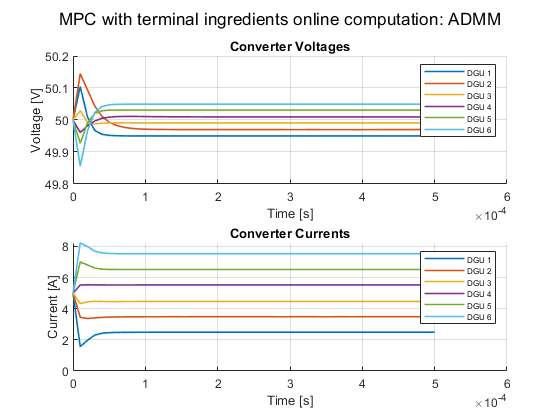

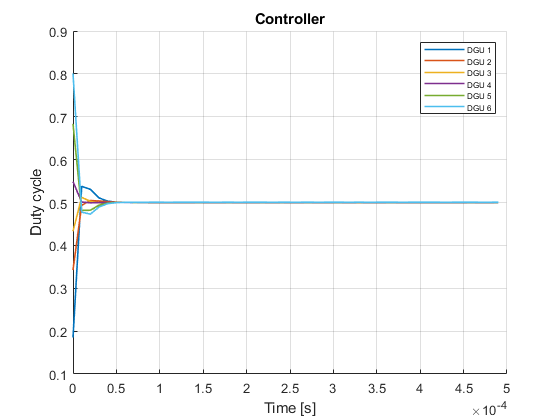

dguNet.plot_DGU_system(XADMM,UADMM, config, control_type, dguNet, simStart,activeDGU); % plot results

- With centralized optimization

control_type = "MPC with terminal ingredients online computation: Central Unit";
[X,U, ~] = sim.mpc_DGU_tracking(@trackingMPC_reconf, x0, length_sim, dguNet, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf -- 
 ---- Simulation step 1 ---- 
---- Simulation step 2 ---- 
---- Simulation step 3 ---- 
---- Simulation step 4 ---- 
---- Simulation step 5 ---- 
---- Simulation step 6 ---- 
---- Simulation step 7 ---- 
---- Simulation step 8 ---- 
---- Simulation step 9 ---- 
---- Simulation step 10 ---- 
---- Simulation step 11 ---- 
---- Simulation step 12 ---- 
---- Simulation step 13 ---- 
---- Simulation step 14 ---- 
---- Simulation step 15 ---- 
---- Simulation step 16 ---- 
---- Simulation step 17 ---- 
---- Simulation step 18 ---- 
---- Simulation step 19 ---- 
---- Simulation step 20 ---- 
---- Simulation step 21 ---- 
---- Simulation step 22 ---- 
---- Simulation step 23 ---- 
---- Simulation step 24 ---- 
---- Simulation step 25 ---- 
---- Simulation step 26 ---- 
---- Simulation step 27 ---- 
---- Simulation step 28 ---- 
---- Simulation step 29 ---- 
---- Simulation step 30 ---- 
---- Simulation step 31 ---- 
---- Simulation step 32 ---- 


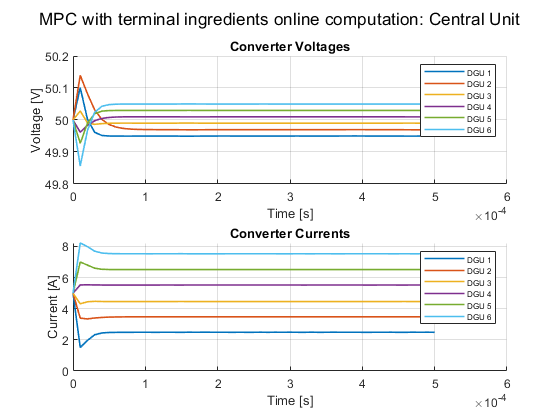

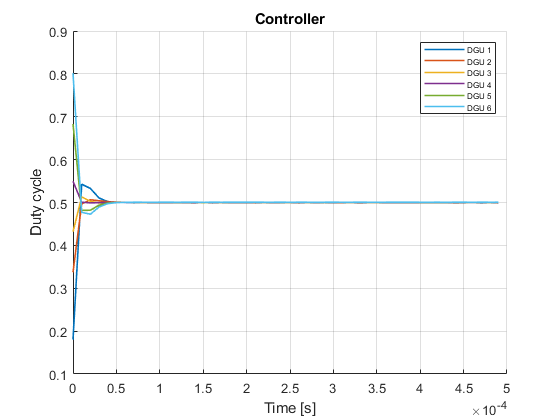

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart,activeDGU); % plot results

One can also plot the evolution of the terminal set throughout the simulation

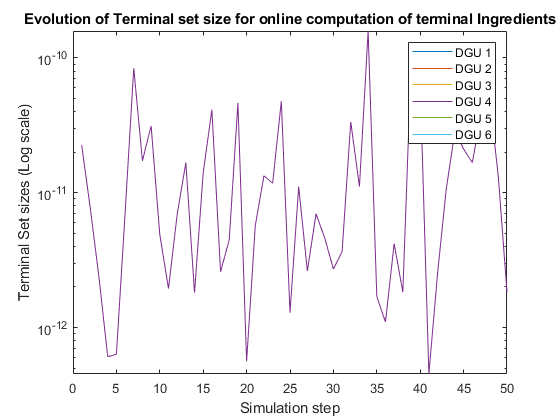

alphaEvolArr = cell2mat(alphaEvol);
lgd = "DGU " + string(dguNet.activeDGU);
figure()
semilogy(abs(alphaEvolArr(dguNet.activeDGU, :)'));
hold on
title("Evolution of Terminal set size for online computation of terminal Ingredients")
xlabel("Simulation step");
ylabel("Terminal Set sizes (Log scale)")
legend(lgd);
hold off

- Compute the tracking error for the online MPC with reconfigurable terminal ingredients

error_mpc_online_ADMM = utils.tracking_error(XADMM,UADMM,config,dguNet,activeDGU)

error_mpc_online_ADMM = 4.4831

error_mpc_online_Central = utils.tracking_error(X,U,config,dguNet,activeDGU)

error_mpc_online_Central = 4.4961

relativeError_onlineMPC = abs(error_mpc_online_ADMM - error_mpc_online_Central)/...
                            min(error_mpc_online_ADMM, error_mpc_online_Central)*100

relativeError_onlineMPC = 0.2891

#### Test MPC without reconfigurable terminal ingredients (also $\Delta$ Formulation)

$\mathbb{X}_f^i = \{ x_i \in \mathbb{R}^m |  V_f^i(x_i) \leq \alpha_i\}$ where $V_f^i(x_i) = x_i^T P_i x_i$ and $\alpha_i^+ = \alpha_i + x_{Ni}^T(N) \Gamma_i 
 x_{Ni} (N)$

- **Using Lyapunov terminal constraints to get **$\alpha_i$

dguNet_delta = dguNet; % make a copy of actual DGU network for delta formulation
delta_config = true;
passivity = false; % set passivity boolean to false
dguNet_delta = dguNet_delta.compute_Ref_Constraints(delta_config); % constraints in delta formulation
[x0_delta, ~, ~] = utils.tuningParam(dguNet_delta, delta_config,passivity);

Compute $P_i$, $\Gamma_i$, $\alpha_i$

[dguNet_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724    0.0000         0         0    0.2862    0.0000    0.5724    0.0000



ans = "Local feedback control laws K_N3"

   1.0e-03 *

    0.2555   -0.0000         0         0    0.3194   -0.0000    0.4471         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615   -0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



ans = "Local feedback control laws K_N6"

   1.0e-03 *

    0.4038    0.0000         0         0



sprintf("Initial terminal set constrait alpha = %d", alpha_i)

ans = "Initial terminal set constrait alpha = 1.205337e-01"

alpha = alpha_i*ones(nb_subsystems,1); % same alpha for every subsystem @ beginning
config = "DISTRIBUTED";

Simulate system with online MPC and $\alpha_i$ update outside of the MPC

- Using ADMM

control_type = "MPC with offline computation of terminal ingredients: ADMM";
[XdeltADMM, UdeltADMM, alphaEvolution] = sim.mpc_sim_DGU_delta(@mpc_delta_admm, x0_delta, length_sim, dguNet_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);

--INFO: Using controller mpc_delta_admm -- 
 ---- Simulation step 1 ---- 
Max elapsed time for a system to converge 9.036230e-02 and max number of iterations 44 
Average time in iteration 2.053689e-03 
---- Simulation step 2 ---- 
Max elapsed time for a system to converge 3.180420e-02 and max number of iterations 21 
Average time in iteration 1.514486e-03 
---- Simulation step 3 ---- 
Max elapsed time for a system to converge 2.073030e-02 and max number of iterations 13 
Average time in iteration 1.594638e-03 
---- Simulation step 4 ---- 
Max elapsed time for a system to converge 1.421700e-02 and max number of iterations 8 
Average time in iteration 1.777125e-03 
---- Simulation step 5 ---- 
Max elapsed time for a system to converge 1.057050e-02 and max number of iterations 6 
Average time in iteration 1.761750e-03 
---- Simulation step 6 ---- 
Max elapsed time for a system to converge 5.101900e-03 and max number of iterations 3 
Average time in iteration 1.700633e-03 
---- Simulation 

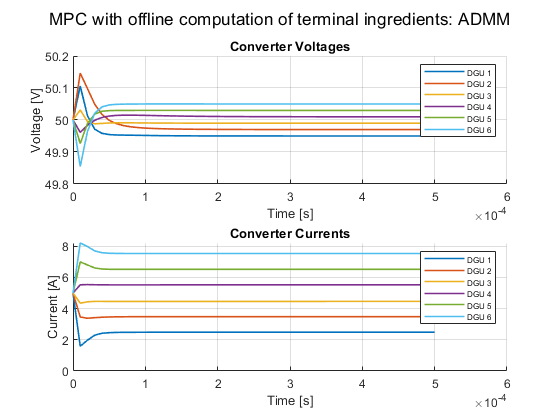

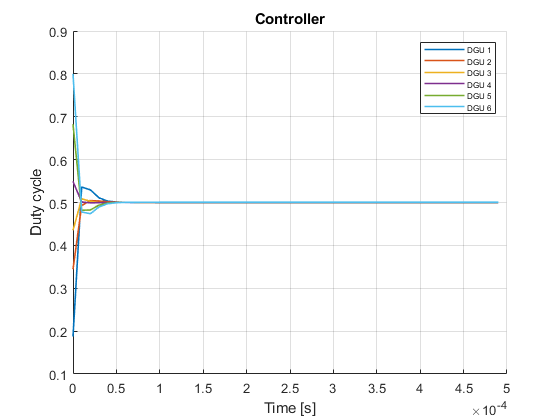

dguNet.plot_DGU_system(XdeltADMM,UdeltADMM, config, control_type, dguNet_delta, simStart, activeDGU)

- Using centralized optimization

control_type = "MPC with offline computation of terminal ingredients: Central Unit";
[Xdelt, Udelt, ~] = sim.mpc_sim_DGU_delta(@mpc_delta, x0_delta, length_sim, dguNet_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);

--INFO: Using controller mpc_delta -- 
 ---- Simulation step 1 ---- 
---- Simulation step 2 ---- 
---- Simulation step 3 ---- 
---- Simulation step 4 ---- 
---- Simulation step 5 ---- 
---- Simulation step 6 ---- 
---- Simulation step 7 ---- 
---- Simulation step 8 ---- 
---- Simulation step 9 ---- 
---- Simulation step 10 ---- 
---- Simulation step 11 ---- 
---- Simulation step 12 ---- 
---- Simulation step 13 ---- 
---- Simulation step 14 ---- 
---- Simulation step 15 ---- 
---- Simulation step 16 ---- 
---- Simulation step 17 ---- 
---- Simulation step 18 ---- 
---- Simulation step 19 ---- 
---- Simulation step 20 ---- 
---- Simulation step 21 ---- 
---- Simulation step 22 ---- 
---- Simulation step 23 ---- 
---- Simulation step 24 ---- 
---- Simulation step 25 ---- 
---- Simulation step 26 ---- 
---- Simulation step 27 ---- 
---- Simulation step 28 ---- 
---- Simulation step 29 ---- 
---- Simulation step 30 ---- 
---- Simulation step 31 ---- 
---- Simulation step 32 ---- 
---- Simu

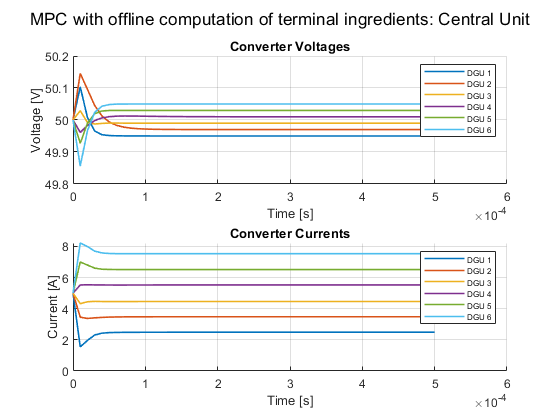

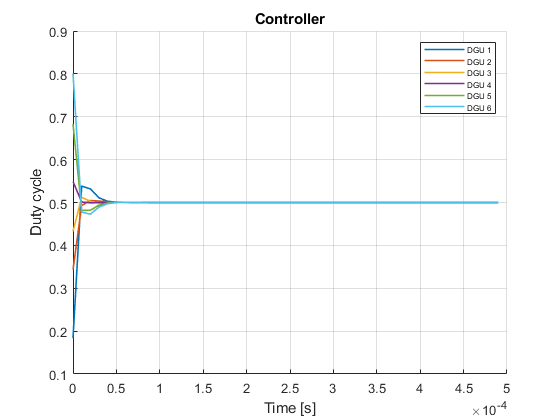

dguNet_delta.plot_DGU_system(Xdelt,Udelt, config, control_type, dguNet_delta, simStart, activeDGU)

One can also plot the evolution of the terminal set throughout the simulation

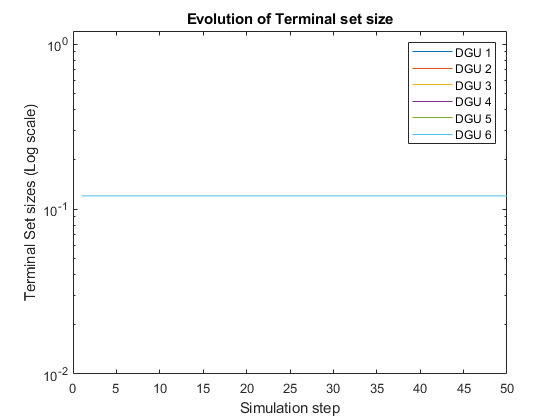

alphaEvolArray = cell2mat(alphaEvolution);
lgd = "DGU " + string(dguNet.activeDGU);
figure()
semilogy(abs(alphaEvolArray(dguNet_delta.activeDGU, :)'));
hold on
title("Evolution of Terminal set size")
xlabel("Simulation step");
ylabel("Terminal Set sizes (Log scale)")
legend(lgd);
hold off

- Compute the tracking error for the online distributed MPC with offline distributed initial terminal set synthesis

error_mpc_offline_ADMM = utils.tracking_error(XdeltADMM,UdeltADMM,config,dguNet_delta,activeDGU)

error_mpc_offline_ADMM = 4.4730

error_mpc_offline_Central = utils.tracking_error(Xdelt,Udelt,config,dguNet_delta,activeDGU)

error_mpc_offline_Central = 4.4866

relativeError_offlineMPC = abs(error_mpc_offline_ADMM - error_mpc_offline_Central)/...
                            min(error_mpc_offline_ADMM, error_mpc_offline_Central)*100

relativeError_offlineMPC = 0.3027